% Define the main directory containing the "SubXX" folders
mainDir = '.\Data_Lab'

% List all "SubXX" folders in the main directory
subDirs = dir(fullfile(mainDir, 'Sub*'));

% Initialize variables to store combined data
errorData = [];  % To store the error data
stimulusData = {};  % To store stimulus types (Bar, Body)
subjectIDs = {};  % To store subject IDs
alldata = table();
% Loop over each "SubXX" folder
for i = 1:length(subDirs)
    subFolder = subDirs(i).name;
    testFolder = fullfile(mainDir, subFolder, 'test');
    
    % Find the .mat file in the "test" folder
    matFile = dir(fullfile(testFolder, [subFolder, '_test_*.mat']));
    
    if ~isempty(matFile)
        % Load the .mat file
        matFilePath = fullfile(testFolder, matFile.name);
        data = load(matFilePath, 'T');
        
        % Extract the table "T" from the .mat file
        T = data.T;
        alldata = [alldata; data.T];
        % Extract the error data (18th column)
        errors = T{:, 18};
        
        % Extract the stimulus data (8th column)
        stimuli = T{:, 8};
        
        % Append the data to the arrays
        meanError(i,1) = mean(errors(strcmp(stimuli, 'Bar')));
        meanError(i,2) = mean(errors(strcmp(stimuli, 'Body')));
        errorData = [errorData; errors];  % Combine the error data
        stimulusData = [stimulusData; stimuli];  % Combine the stimulus data
       % subjectIDs = [subjectIDs; repmat({subFolder}, length(errors), 1)];  % Add the subject ID
    end
end

alldata = alldata(abs(alldata.Error) <20, :);


% Create a new table with the combined data
combinedTable = table(subjectIDs, stimulusData, errorData, 'VariableNames', {'SubjectID', 'Stimulus', 'Error'});

% Perform t-tests for each stimulus type against 0
barErrors = errorData(strcmp(stimulusData, 'Bar'));
bodyErrors = errorData(strcmp(stimulusData, 'Body'));

% t-test for Bar stimulus
[~, pBar] = ttest(meanError(:,1), 0);

% t-test for Body stimulus
[~, pBody] = ttest(meanError(:,2), 0);

% t-test between Bar and Body stimuli
[~, pStimulus] = ttest2(barErrors, bodyErrors);

% Display the t-test results
fprintf('T-test for Bar stimulus vs. 0: p-value = %.4f\n', pBar);

T-test for Bar stimulus vs. 0: p-value = 0.0000


fprintf('T-test for Body stimulus vs. 0: p-value = %.4f\n', pBody);

T-test for Body stimulus vs. 0: p-value = 0.3312


fprintf('T-test between Bar and Body stimuli: p-value = %.4f\n', pStimulus);

T-test between Bar and Body stimuli: p-value = 0.0244



% Prepare data for plotting
groupLabels = {'Bar', 'Body'};
meanErrors = [mean(meanError(:,1)), mean(meanError(:,2))]

meanErrors =     0.9111    0.2111


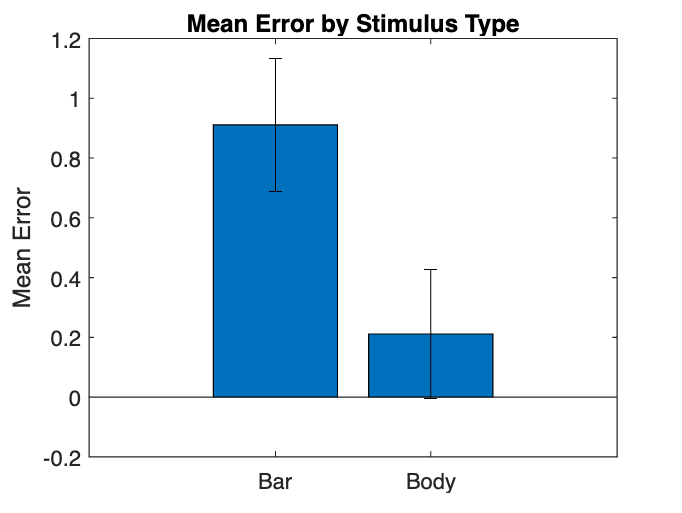

Ranked Subjects by Total Errors:


Subject: Sub12, Total Errors: 622.00
Subject: Sub01, Total Errors: 521.00
Subject: Sub15, Total Errors: 493.00
Subject: Sub10, Total Errors: 481.00
Subject: Sub05, Total Errors: 428.00
Subject: Sub03, Total Errors: 416.00
Subject: Sub02, Total Errors: 395.00
Subject: Sub09, Total Errors: 338.00
Subject: Sub11, Total Errors: 331.00
Subject: Sub06, Total Errors: 329.00
Subject: Sub13, Total Errors: 325.00
Subject: Sub04, Total Errors: 315.00
Subject: Sub14, Total Errors: 292.00
Subject: Sub08, Total Errors: 290.00
Subject: Sub07, Total Errors: 198.00


stderrErrors = [std(barErrors) / sqrt(length(barErrors)), std(bodyErrors) / sqrt(length(bodyErrors))];

% Plot the results in a bar graph
figure;
bar(meanErrors);
hold on;
errorbar(1:length(meanErrors), meanErrors, stderrErrors, 'k', 'LineStyle', 'none');
xticks(1:length(meanErrors));
xticklabels(groupLabels);
ylabel('Mean Error');
title('Mean Error by Stimulus Type');
hold off;